# **Effective Solar House Design**

*Authors: *Drew Pang and Kelly Stellmacher

## Question:

Traditional houses attempt to separate the temperature-controlled air from the outside air but add windows to let natural light. While these homes have gotten more energy efficient due to advances in insulation, solar houses can be more energy efficient. By contrast, solar homes attempt to heat themselves through large windows facing south. During Winter, the sun shines into the house and radiates heat energy off of the floor. However, during the Summer when the sun is higher, the soffit blocks the sun from entering the already warm house. 

 We can use thermodynamics to model a solar house to estimate the effects of parameters. Let's take a look at the specific solar house we are modeling:

Question: What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?

Why is this interesting? We are asking a design question, and through our model, we will be able to determine the effects of the thickness of our walls. This may help architects and homeowners looking to design and build solar houses.

## **Method/model:**

We are going to answer our question by tracking the flow of energy from the sun into the floor, then into the room and out the walls. This will allow us to determine the change in temperature of the room over time. We began with energy transferring directly from the sun into the room, but advised to introduce an intermediary stock that stores the energy from the sun before emmiting it into the room. We also grappled with the possibility of adding another convective flow from the walls of the house to the outside air, but decided to begin by only implementing a conduction flow from the rom to the outside air through the walls. 

We developed the following scematic diagram:

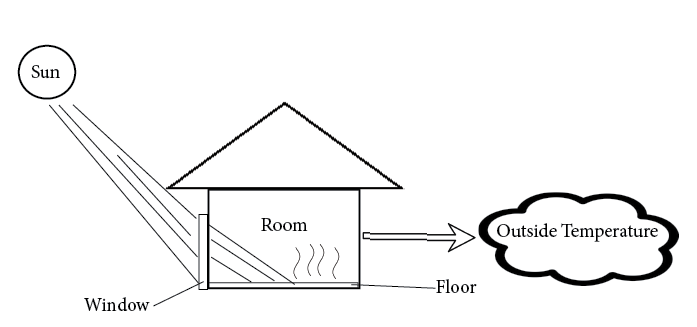

Where energy radiates from the sun, through the window of the house, into the floor, and then conducts from the floor into the air contained in the house. The energy then leaves the house via convecting through the walls. 

From the scematic, we developed the following stock and flow diagram:

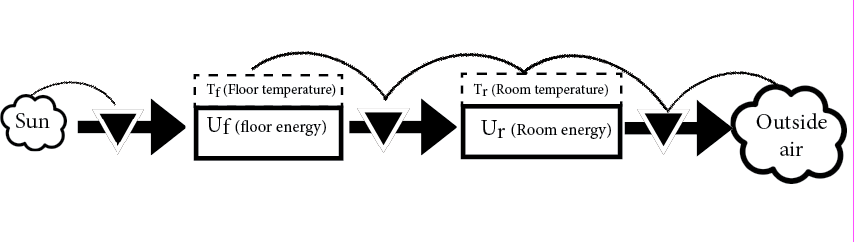

Where the flow from the sun to the floor is radiation, the flow from the floor to the room is convection, and the flow from the room to the outside air is conduction. 

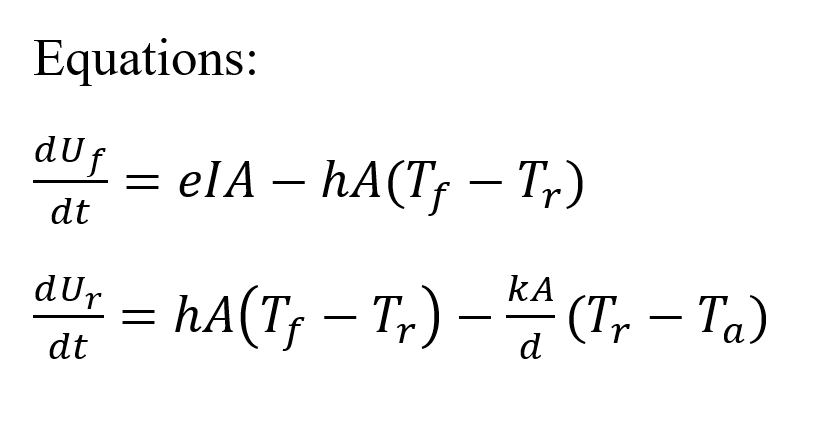

Through research into the different parameters of the system, we managed to gain reliable approximations for all of the factors contributing to our model. The parameter settings needed to be revised multiple times for the final values to be settled on.  

Parameters: 

- Tf(1) = 293; floor starting temperature (K)

- Tr(1) = 293; house int starting temperature (K)

- Ta = 263.56; external temperature (K)

- w = 10; sidelength of house (m)

- wt = .30; thickness of walls (m)

- wf = .05715; thickness of floor (m)

- I = 170.14; incident solar radiation (w/m^2)

- e = 0.885; emmisivity of floor (oak) (j/m^2)

- h_a = 0.026; thermal conductivity of air (w/m)

- h_w = 0.05; thermal conductivity of walls (insulation) (w/m)

- h_f = 0.170; thermal conductivity of floor (wood) (w/m)

- s_f = 1850; specific heat of floor(j/kg C)

- s_a = 1005; specific heat of air (j/kg C)

- d = 1.293; density of air (kg/m^3)

- d_f = 745; density of floor (kg/m^3)

Assumptions for our model inlcude:

- The structural integrity of the house will not be jepordized based on the material the walls are composed of. 

- The roof is made of the same material as the walls. 

- The aperture of the window will remain constant.

- The Sun zenith angle remains the same.

- The house is empty: no people or furniture is present to alter energy content of the room

- There is nothing obstructing the sunlight from reaching the house. 

All of these assumptions are made in order to keep this model simple and possible to program. However, if we wished to increase the accuracy, we could take our assumptions and act on them. For example, if we wanted to make the house realistically liveable, we would have to account for structural integrity and openings where people can enter and exit. 

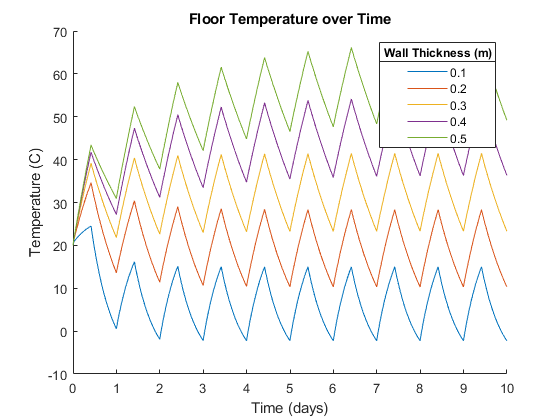

figure(1);
clf; hold on;
title('Floor Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')

for wt = 0.1:0.1:0.5
    
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt(:,1));
end
 legend('0.1', '0.2', '0.3', '0.4','0.5')
 title(legend,'Wall Thickness (m)')

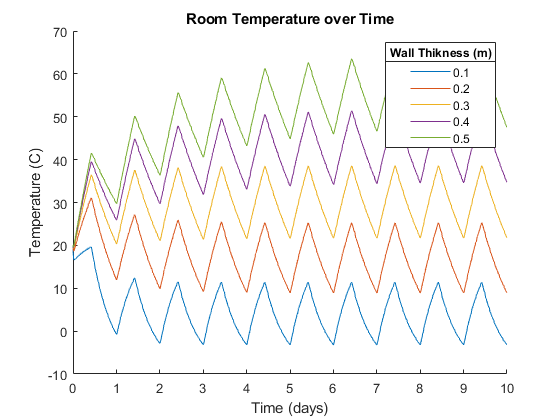

 
figure(2)
clf; hold on;
title('Room Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
 
for wt = 0.1:0.1:0.5
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt (:,2));
end 
legend('0.1', '0.2', '0.3', '0.4','0.5')
title(legend,'Wall Thikness (m)')

Verifying this model is difficult because the total energy is not able to be tracked, as it is contained in stocks that are not fully monitored. For example, the energy leaving the room into the outside air is contained in the walls before it is released, leading to an unknown stock. 

If we had more time and resources for this project, we could verify the results by constructing a miniature model house with the materials we specified, setting up a controllable heat source, then monitor the change in temperature over time.  

## **Results:**

Sweeping the parameter of the wall thickness yields an incremental increase in room temperature as the wall's thickness increases. The majority of wall thicknesses render the room temperature too hot for humans to survive living in it. The highest thickness of 0.5m causes the room to heat to a maximum temperature of over 60 degrees Celcius during the day and about 45 degrees Celcius in the night. The lowest thickness of 0.5m results in a drop to below zero during the night, which is livable, but not ideal living conditions. The only thickness that preserves a range of temperatures over time is 0.2m because it causes the temperature to rise to about 28 and fall to about 10 degrees Celsius. 

## **Interpretation:**

Our question was 'What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?' and the quick answer is that any thickness greater than 0.2 will yield a minimum internal temperature. However, the ideal thickness is about 0.2m because this also prevents the maximum temperature from exceeding a tolerable level. 

This answer is good in that it reveals more about the situation than was initially expected. We were concerned about the house becoming too cold, but the model signified that the true situation may cause the house to become too hot. Despite its values, it is important to keep in mind that this model is limited in multiple manners. 

Our model is limited in that it only accounts for conduction through the walls, but fails to account for whether there are any doors or open windows where energy could convect directly out of the house, which could cause the temperature inside to decrease at a faster rate. It is also limited to a very specific location with a specific amount of solar radiation acting on it. 

If we were to continue iterating on our model, we could lengthen the timeframe to a year and examine the impact of changing seasons. We could also add a flow from the floor into the ground to more accurately simlate the change in energy in the house. 